% ----------------------------------------------
% This program formulates the minimimal variance mechanism problem into a
% linear programing problem, and solves it using the built-in solver in Matlab.
% Comments are adquent in the code. 
% If you have any question,
% please feel free to contact Fei Wei at feiwei@nus.edu.sg
% ----------------------------------------------

close all
clear

% eps = 2; % privacy parameter
delta = 0; % privacy parameter
r=0.5; % geometric series constant
axRatio = 3; %the ratio amax/xmax

xmax = 1;
N = 4; % TotAal number of bins in [-xmax,xmax]
x_bin_size = 2*xmax/N;
x_grid = linspace(-xmax+0.5*x_bin_size,xmax-0.5*x_bin_size,N)

x_grid =    -0.7500   -0.2500    0.2500    0.7500



% We assign a distribution to X\in x_grid
% In the write-up, this is the data distribution

x_P = ones(1,N)/N; % Uniform distribution

% x_P = x_grid.^2;
% x_P = x_P./ sum(x_P);

% x_P = x_grid-min(x_grid);
% x_P = x_P./sum(x_P);

% figure
% plot(x_grid,x_P,'o',LineWidth=1.5);
% xlabel("x",FontSize=13);
% ylabel("P(x)",FontSize=13);
% grid on

% [totalVariance,pMatrix] = opt_variance(eps,r,axRatio,x_grid,x_P);

% For testing, we sample a sequence of epsilon values
eps_grid = exp(linspace(0,log(8),20));

% The variance of optimal mechanism
VarOpt = zeros(1,length(eps_grid));
VarOptWorst = zeros(1,length(eps_grid));
for i = 1:length(eps_grid)
    [varVector,pMatrix,a_grid] =... 
        opt_variance(eps_grid(i),delta,r,axRatio,x_grid,x_P);
    VarOpt(i) = x_P*varVector;
    VarOptWorst(i) = max(varVector);
end

--------------------------------
eps = 1.000000, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.0278   -0.1110   -0.1249    0.0278


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     1.0822    0.9243    0.9243    1.0822


--------------------------------
eps = 1.115658, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

   -0.2082   -0.5551    0.4163    0.2776


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.9987    0.8119    0.8119    0.9987


--------------------------------
eps = 1.244693, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.2845    0.0659         0    0.1110


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.9111    0.7012    0.7012    0.9111


--------------------------------
eps = 1.388651, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

    0.1527   -0.0520   -0.0139   -0.0278


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.8204    0.5968    0.5968    0.8204


--------------------------------
eps = 1.549260, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

    0.1388    0.0347   -0.2082   -0.2776


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.7304    0.5168    0.5168    0.7304


--------------------------------
eps = 1.728444, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

    0.0746   -0.0312   -0.0069    0.6106


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.6100    0.4743    0.4743    0.6100


--------------------------------
eps = 1.928352, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

    0.5562    0.0694    0.1041    0.4163


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.5207    0.4039    0.4039    0.5207


--------------------------------
eps = 2.151381, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

    0.4608   -0.4575   -0.1735    0.1388


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.4145    0.3599    0.3599    0.4145


--------------------------------
eps = 2.400205, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

   -0.8251   -0.1854    0.2776    0.4163


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.4002    0.2216    0.2216    0.4002


--------------------------------
eps = 2.677808, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

    0.0006    0.0395         0   -0.1804


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.3202    0.1620    0.1620    0.3202


--------------------------------
eps = 2.987518, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

   -0.1496   -0.1442   -0.0867   -0.1735


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.2399    0.1134    0.1134    0.2399


--------------------------------
eps = 3.333048, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

   -0.1090    0.1523   -0.0060   -0.9714


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.1713    0.0784    0.0784    0.1713


--------------------------------
eps = 3.718541, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

    0.1635   -0.0419   -0.0344    0.8413


Distribution validity check (should be all ones):


ans =      1     1     1     1


Variance vector:


ans =     0.1178    0.0517    0.0517    0.1178


--------------------------------
eps = 4.148620, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

    0.1057   -0.0008    0.0431   -0.5464


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.0774    0.0329    0.0329    0.0774


--------------------------------
eps = 4.628441, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

   -0.0585   -0.0054    0.0027    0.3036


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.0482    0.0200    0.0200    0.0482


--------------------------------
eps = 5.163757, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

   -0.0435   -0.0154    0.0136    0.4353


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.0284    0.0116    0.0116    0.0284


--------------------------------
eps = 5.760986, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

    0.0191   -0.0089    0.0021   -0.5268


Distribution validity check (should be all ones):


ans = 1×4
    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans = 1×4
    0.0157    0.0063    0.0063    0.0157


--------------------------------
eps = 6.427290, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1×4
1.0e-16 *

    0.0193    0.0060   -0.0022    0.4737


Distribution validity check (should be all ones):


ans = 1×4
    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans = 1×4
    0.0081    0.0032    0.0032    0.0081


--------------------------------
eps = 7.170657, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1×4
1.0e-11 *

    0.1301   -0.0000    0.0000    0.0000


Distribution validity check (should be all ones):


ans = 1×4
    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans = 1×4
    0.0038    0.0015    0.0015    0.0038


--------------------------------
eps = 8.000000, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1×4
1.0e-18 *

   -0.2168   -0.0301   -0.0449    0.2922


Distribution validity check (should be all ones):


ans = 1×4
    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans = 1×4
    0.0017    0.0007    0.0007    0.0017


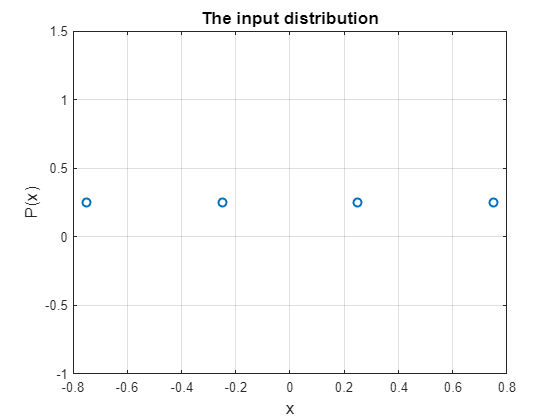

% The variance vector of Laplace mechanism
VarLaplace = zeros(1,length(eps_grid));
for i = 1:length(eps_grid)
    VarLaplace(i) = 8/(eps_grid(i))^2;
end

% The variance vector of Duchi mechanism
VarDuchi = zeros(1,length(eps_grid));
VarDuchiWorst = zeros(1,length(eps_grid));
var_duchi = @(ti,eps) ((exp(eps)+1)/(exp(eps)-1)).^2 - ti.^2;
for i = 1:length(eps_grid)
    temp = var_duchi(x_grid,eps_grid(i));
    VarDuchi(i) = temp *x_P';
    VarDuchiWorst(i) = max(temp);
end

% The variance vector of piece-wise mechanism
VarPiecewise = zeros(1,length(eps_grid));
VarPiecewiseWorst = zeros(1,length(eps_grid));
var_piecewise = @(ti,eps) ti.^2./(exp(eps/2)-1) + (exp(eps/2)+3)/3/(exp(eps/2)-1)^2;
for i = 1:length(eps_grid)
    temp = var_piecewise(x_grid,eps_grid(i));
    VarPiecewise(i) = temp *x_P';
    VarPiecewiseWorst(i) = max(temp);
end

% The variance vector of Hybrid mechanism
VarHybrid = zeros(1,length(eps_grid));
VarHybridWorst = zeros(1,length(eps_grid));
alpha = @(eps) sign(max(eps-0.61,0))*(1-exp(-eps/2));
var_hybrid = @(ti,eps) alpha(eps)*var_piecewise(ti,eps) + (1-alpha(eps))*var_duchi(ti,eps);
for i = 1:length(eps_grid)
    temp = var_hybrid(x_grid,eps_grid(i));
    VarHybrid(i) = temp *x_P';
    VarHybridWorst(i) = max(temp);
end

% The plots

figure;
plot(x_grid,x_P,'o',LineWidth=1.5);
title("The input distribution",FontSize=13);
xlabel("x",FontSize=13);
ylabel("P(x)",FontSize=13);
grid on

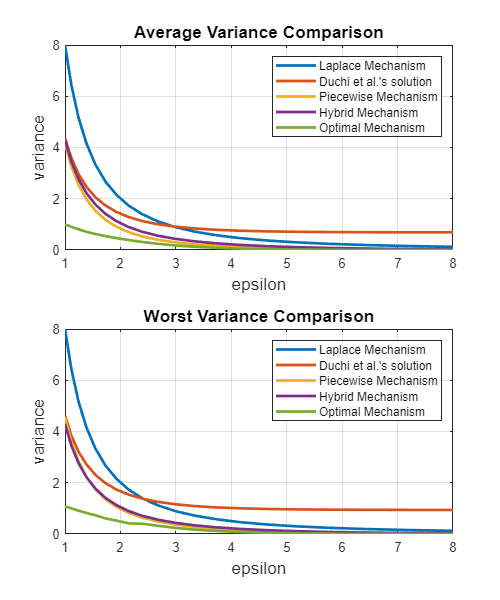


figure;
f = figure;
f.Position = [0 0 500 600];

subplot(2,1,1)
plot(eps_grid,VarLaplace,LineWidth=2);
hold on
plot(eps_grid,VarDuchi,LineWidth=2);
hold on
plot(eps_grid,VarPiecewise,LineWidth=2);
hold on
plot(eps_grid,VarHybrid,LineWidth=2);
hold on
plot(eps_grid,VarOpt,LineWidth=2);

title("Average Variance Comparison",FontSize=13)
xlabel("epsilon",FontSize=13)
ylabel("variance",FontSize=13)
legend("Laplace Mechanism", "Duchi et al.'s solution",...
    "Piecewise Mechanism","Hybrid Mechanism","Optimal Mechanism")
grid on

subplot(2,1,2)
plot(eps_grid,VarLaplace,LineWidth=2);
hold on
plot(eps_grid,VarDuchiWorst,LineWidth=2);
hold on
plot(eps_grid,VarPiecewiseWorst,LineWidth=2);
hold on
plot(eps_grid,VarHybridWorst,LineWidth=2);
hold on
plot(eps_grid,VarOptWorst,LineWidth=2);
title("Worst Variance Comparison",FontSize=13)
xlabel("epsilon",FontSize=13)
ylabel("variance",FontSize=13)
legend("Laplace Mechanism", "Duchi et al.'s solution",...
    "Piecewise Mechanism","Hybrid Mechanism","Optimal Mechanism")
grid on

q = 10; % quantization level
% eps = 2; % privacy parameter
delta = 0; % privacy parameter
r=0.5; % geometric series constant
axRatio = 4; %the ratio amax/xmax
eps = 2; % the privacy parameter

xmax = 1;
xmax = floor(xmax*q)/q; % We need to make sure they are integers
M = 2*xmax*q+1; % total amount of x samples
x_grid = linspace(-xmax,xmax,M);

% We assign a distribution to X\in x_grid

x_P = ones(1,M)/M; % Uniform distribution

% x_P = x_grid.^2;
% x_P = x_P./ sum(x_P);

% x_P = x_grid-min(x_grid);
% x_P = x_P./sum(x_P);

[varVector,pMatrix,a_grid] =...
    opt_variance(eps,delta,r,axRatio,x_grid,x_P);

--------------------------------
eps = 2.000000, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-14 *

   -0.0441   -0.0290    0.0057    0.0073   -0.0051   -0.1915    0.0008   -0.0007   -0.1023    0.0031   -0.0278   -0.0051    0.0073    0.0014   -0.0122    0.0736    0.0003    0.0026    0.0016    0.0268   -0.0077


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     1.0336    0.8948    0.8684    0.8367    0.8026    0.7674    0.7382    0.7061    0.6662    0.6263    0.5983    0.6263    0.6662    0.7061    0.7382    0.7674    0.8026    0.8367    0.8684    0.8948    1.0336


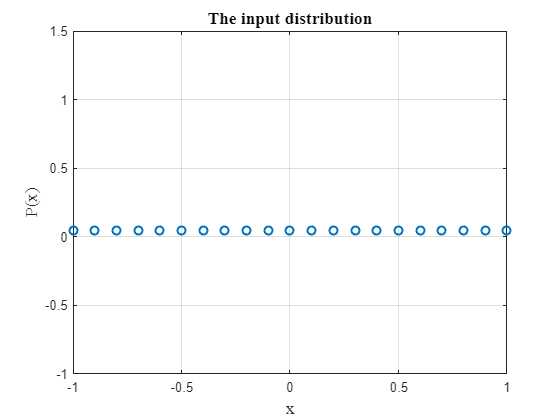

% The plots

figure;
plot(x_grid,x_P,'o',LineWidth=1.5);
title("The input distribution",'FontSize',13,'FontName','Times');
xlabel("x",'FontSize',13,'FontName','Times');
ylabel("P(x)",'FontSize',13,'FontName','Times');
grid on

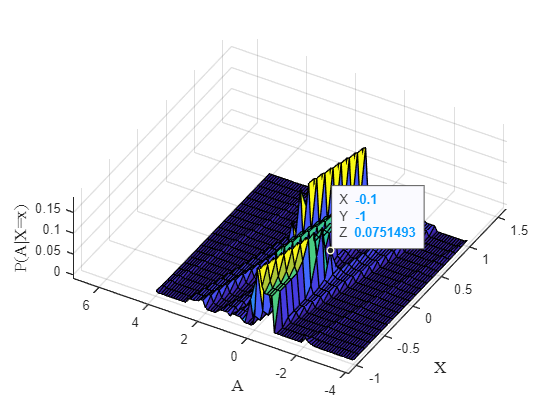


figure
[X_grid,Y_grid] = meshgrid(-x_grid,a_grid);
surf(X_grid,Y_grid,pMatrix');
xlabel("X",'FontSize',13,'FontName','Times');
ylabel("A",'FontSize',13,'FontName','Times');
zlabel("P(A|X=x)",'FontSize',13,'FontName','Times');